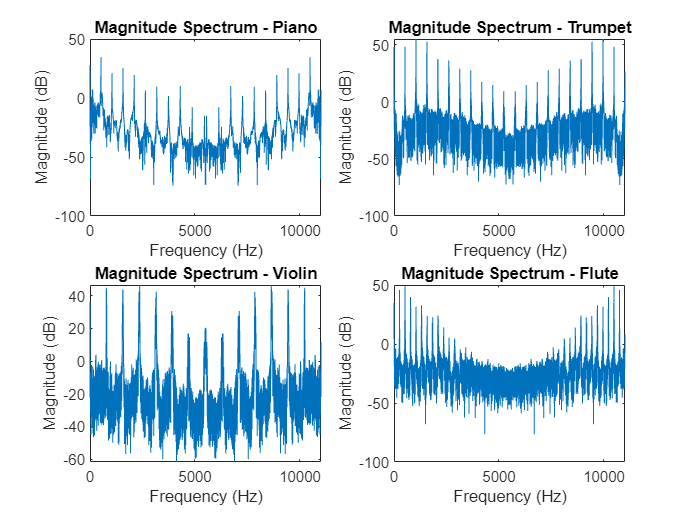

fileNames = {'C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\piano2.wav', 'C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\trumpet2.wav', 'C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\violin2.wav', 'C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\flute2.wav'};
fundamentalFrequencies = zeros(1, numel(fileNames));

for i = 1:numel(fileNames)
    [audioSignal, sampleRate] = audioread(fileNames{i});
    fftResult = fft(audioSignal);
    magnitudeSpectrum = 20*log10(abs(fftResult));
    [~, idx] = max(magnitudeSpectrum);
    fundamentalFrequencies(i) = (idx - 1) * sampleRate / numel(audioSignal);

    subplot(2, 2, i);
    plot((0:(numel(audioSignal)-1)) * sampleRate / numel(audioSignal), magnitudeSpectrum);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(sprintf('Magnitude Spectrum - %s', instrumentNames{i}));
end


instrumentNames = {'Piano', 'Trumpet', 'Violin', 'Flute'};
fprintf('Instrument\tFundamental Frequency (Hz)\n');

Instrument	Fundamental Frequency (Hz)


for i = 1:numel(fileNames)
    fprintf('%s\t\t%.2f\n', instrumentNames{i}, fundamentalFrequencies(i));
end

Piano		523.62
Trumpet		1047.21
Violin		2369.12
Flute		524.33


[pianoAudio, pianoSampleRate] = audioread('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\piano2.wav');

numFluteSamples = 4;
fluteAudio = cell(1, numFluteSamples);
fundamentalFrequencyFlute = zeros(1, numFluteSamples);

for i = 1:numFluteSamples
    fluteFileName = sprintf('C:\\Users\\charu\\OneDrive\\Desktop\\College\\DSP_Lab\\Experiment-3\\flute%d.wav', i);
    [fluteAudio{i}, fluteSampleRate] = audioread(fluteFileName);
    pianoFFT = fft(pianoAudio);
    fluteFFT = fft(fluteAudio{i});
        [~, pianoIdx] = max(abs(pianoFFT));
    [~, fluteIdx] = max(abs(fluteFFT));
    
    fundamentalFrequencyPiano = (pianoIdx - 1) * pianoSampleRate / numel(pianoAudio);
    fundamentalFrequencyFlute(i) = (fluteIdx - 1) * fluteSampleRate / numel(fluteAudio{i});
end

differences = abs(fundamentalFrequencyFlute - fundamentalFrequencyPiano);
[minDifference, minIndex] = min(differences);

fprintf('Fundamental Frequency (Piano2): %.2f Hz\n', fundamentalFrequencyPiano);

Fundamental Frequency (Piano2): 523.62 Hz


fprintf('Fundamental Frequencies (Flute): %.2f Hz, %.2f Hz, %.2f Hz, %.2f Hz\n', fundamentalFrequencyFlute);

Fundamental Frequencies (Flute): 1063.20 Hz, 524.33 Hz, 793.50 Hz, 524.40 Hz


fprintf('β: %d\n', minIndex);

β: 2
